## 1.  Use `bp3.m` to train an 8-2-8 autoencoder.  Use eye(8) for the set of stimulus patterns (`p8.smat`).

rs = rng;
p8.smat = eye(8);
net0 = initnet3(8,2,8,2,2,rs);

a. For the targets, use `p8.tmat = eye(8)`

p8.tmat = eye(8);
neta = bp3(net0,p8,10000,1,0,rs);
acta = forw3(neta,p8)

acta = struct with fields:
    stim: [8×8 double]
     hid: [8×2 double]
     out: [8×8 double]

b. For `p8.tmat` field, try this: 

`i8 = eye(8);` 

`p8.tmat = i8 + i8([2 3 4 5 6 7 8 1] , :) +  i8([8 1 2 3 4 5 6 7] , :) ;`

i8 = eye(8) ;
p8.tmat = i8 + i8([2 3 4 5 6 7 8 1],:) + i8([8 1 2 3 4 5 6 7],:);
p8.tmat

ans =      1     1     0     0     0     0     0     1
     1     1     1     0     0     0     0     0
     0     1     1     1     0     0     0     0
     0     0     1     1     1     0     0     0
     0     0     0     1     1     1     0     0
     0     0     0     0     1     1     1     0
     0     0     0     0     0     1     1     1
     1     0     0     0     0     0     1     1


netb = bp3(net0,p8,10000,1,0,rs);
actb = forw3(netb,p8)

actb = struct with fields:
    stim: [8×8 double]
     hid: [8×2 double]
     out: [8×8 double]

After checking the outputs for accuracy, examine the hidden unit representations.

acta.out

ans =       0.64894     0.060288   2.9439e-05    0.0017083   7.7296e-19   3.7368e-22   2.6408e-15   3.3387e-21
     0.028101      0.96046   4.5264e-21   1.4224e-18   0.00083044    5.716e-20      0.48142   2.5281e-23
   4.3551e-19   4.2767e-22      0.94881     0.028271   1.3915e-19   0.00084951   2.0901e-21      0.31117
   5.6222e-06   1.2561e-08       0.4049      0.53107   1.6857e-21   8.7852e-17   1.4736e-19   1.3928e-14
    3.036e-20   1.8864e-17   2.1333e-20   5.8949e-22      0.84673     0.037979     0.040931   4.0574e-05
   1.0376e-22   1.2065e-20   9.6624e-18   4.8535e-20     0.073916      0.90523   0.00011935     0.052455
   7.7265e-07    0.0011114   7.2705e-22   2.4918e-20     0.057138   2.0826e-15      0.76803   6.2155e-19
   5.7303e-21   3.9117e-23     0.017378    1.742e-05   2.4784e-16     0.069346   1.0899e-18      0.86067


actb.out

ans =             1      0.32869   4.9505e-05   4.2072e-10   1.5549e-09   0.00012227      0.67565      0.99997
      0.85854      0.99999      0.99933       0.1421   4.9801e-05   1.2424e-08   1.2794e-09   0.00038135
      0.85698      0.99999      0.99933      0.14257   5.0404e-05   1.2555e-08   1.2898e-09   0.00037887
   2.4586e-10   0.00044228       0.3218      0.99722            1      0.67887    0.0017924   1.3537e-09
   2.4582e-10   0.00044237      0.32186      0.99722            1      0.67883    0.0017918   1.3533e-09
   0.00015036   2.6476e-09   1.5727e-08   9.1044e-07       0.8922      0.99995            1      0.10784
   0.00015037   2.6478e-09   1.5728e-08   9.1043e-07      0.89219      0.99995            1      0.10784
            1      0.29323   4.6155e-05   4.4982e-10   1.8895e-09   0.00014419      0.70204      0.99997


## 2.  Use bp3.m to train an 8-3-8 autoencoder.  Examine the hidden unit representations using scatter3.

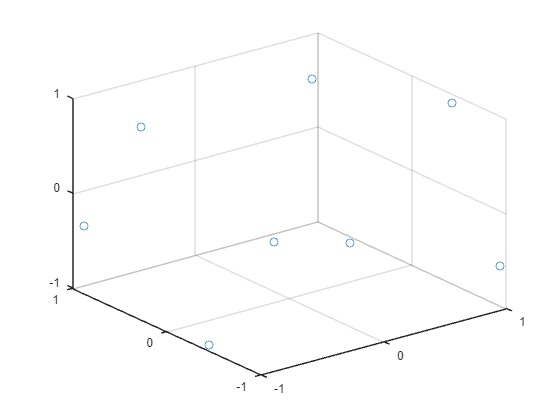

q2net0 = initnet3(8,3,8,2,2,rs);
p8.tmat = eye(8);
q2netfinal = bp3(q2net0,p8,10000,1,0,rs);
q2actfinal = forw3(q2netfinal,p8);

scatter3(q2actfinal.hid(:,1),q2actfinal.hid(:,2),q2actfinal.hid(:,3))

## 3.  Use bp3.m to train a 12-3-12 autoencoder.  Examine the hidden unit representations using scatter3.

p12.smat = eye(12);
p12.tmat = eye(12);
q3net0 = initnet3(12,3,12,2,2,rs);
q3netfinal = bp3(q3net0,p12,10000,1,0,rs);
q3actfinal = forw3(q3netfinal,p12)

q3actfinal = struct with fields:
    stim: [12×12 double]
     hid: [12×3 double]
     out: [12×12 double]

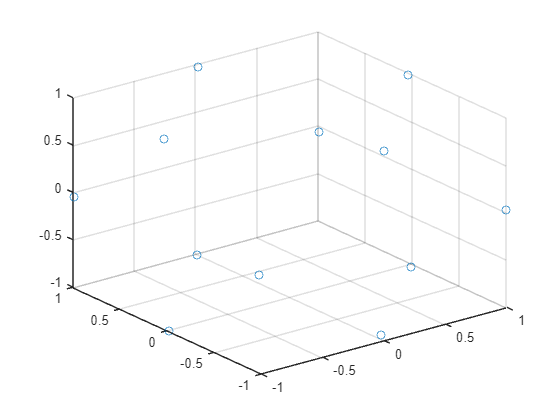


scatter3(q3actfinal.hid(:,1),q3actfinal.hid(:,2),q3actfinal.hid(:,3))